# The Transportation Model and Its Variants

## **Definition of The Transportation Model** 

The problem is represented by the network in **Figure 1**. There are *m* sources and *n* destinations, each represented by a **node**. The **arcs** represent the routes linking the sources and the destinations. Arc (*i*, *j*) joining source *i* to destination *j* carries two pieces of information: the transportation cost per unit, $c_{ij}$, and the amount shipped, $x_{ij}$. The amount of supply at source $i$ is $a_i$, and the amount of demand at destination $j$ is $b_j$. The objective of the model is to minimize the total transportation cost while satisfying all the supply and demand restrictions. 

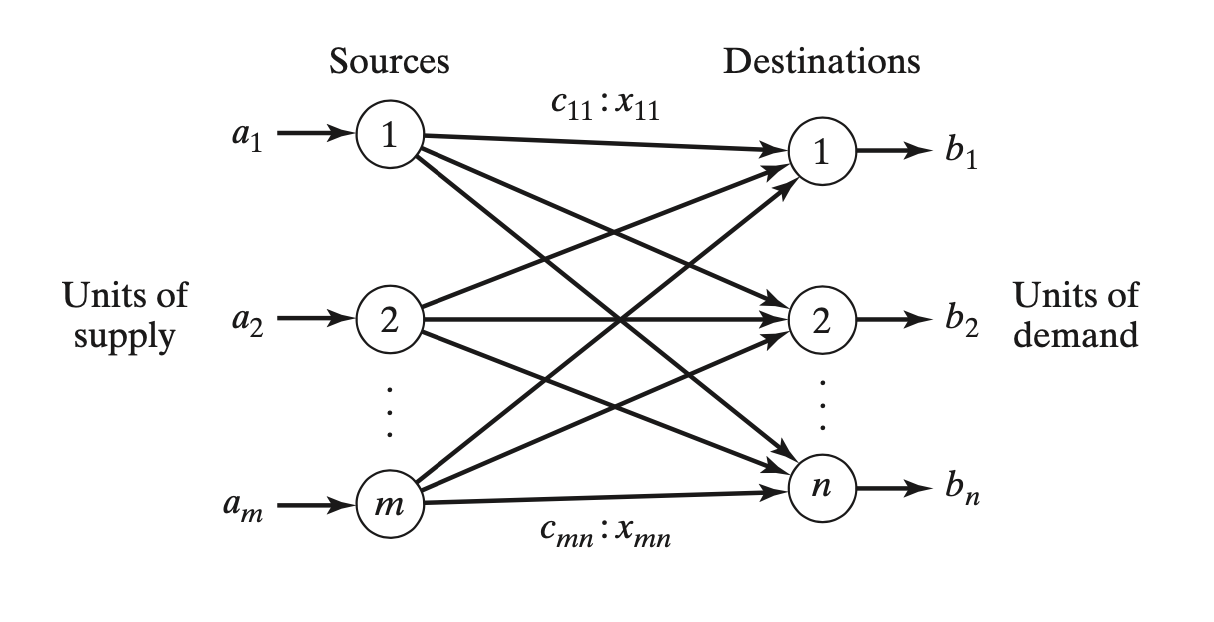 

**จำนวนคำตอบที่เป็นไปได้ทั้งหมด n*m**

**c คือค่าขนส่ง**

**Figure 1:** Representation of the transportation model with nodes and arcs	

## **Example 1: Transportation Problem** 

MG Auto has three plants in Los Angeles, Detroit, and New Orleans and two major distribution centers in Denver and Miami. The quarterly capacities of the three plants are 1000, 1500, and 1200 cars, and the demands at the two distribution centers for the same period are 2300 and 1400 cars. The mileage chart between the plants and the distribution centers is given in **Table 1**. 

The trucking company in charge of transporting the cars charges 8 cents per mile per car. Thus, the transportation costs per car on the different routes, rounded to the closest dollar, are computed from Table 5.1 as shown in **Table 2**.			

**Table 1:** Mileage Chart (ระยะทางจากศูนย์กระจายสินค้าไป 2 เมือง)

 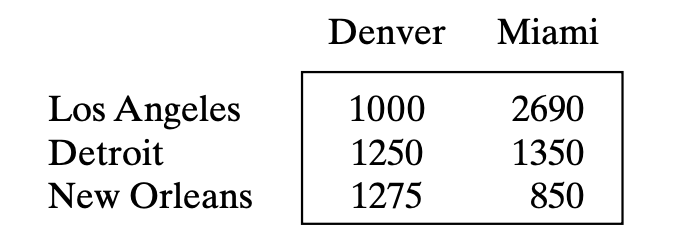 

**Table 2:** Transportation Cost per Car

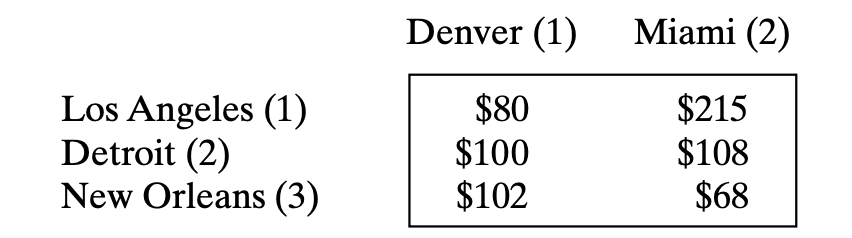

The LP model of the problem can be formulated as follows.

แบ่งเป็นข้อจำกัดฝั่ง demand กับ supply

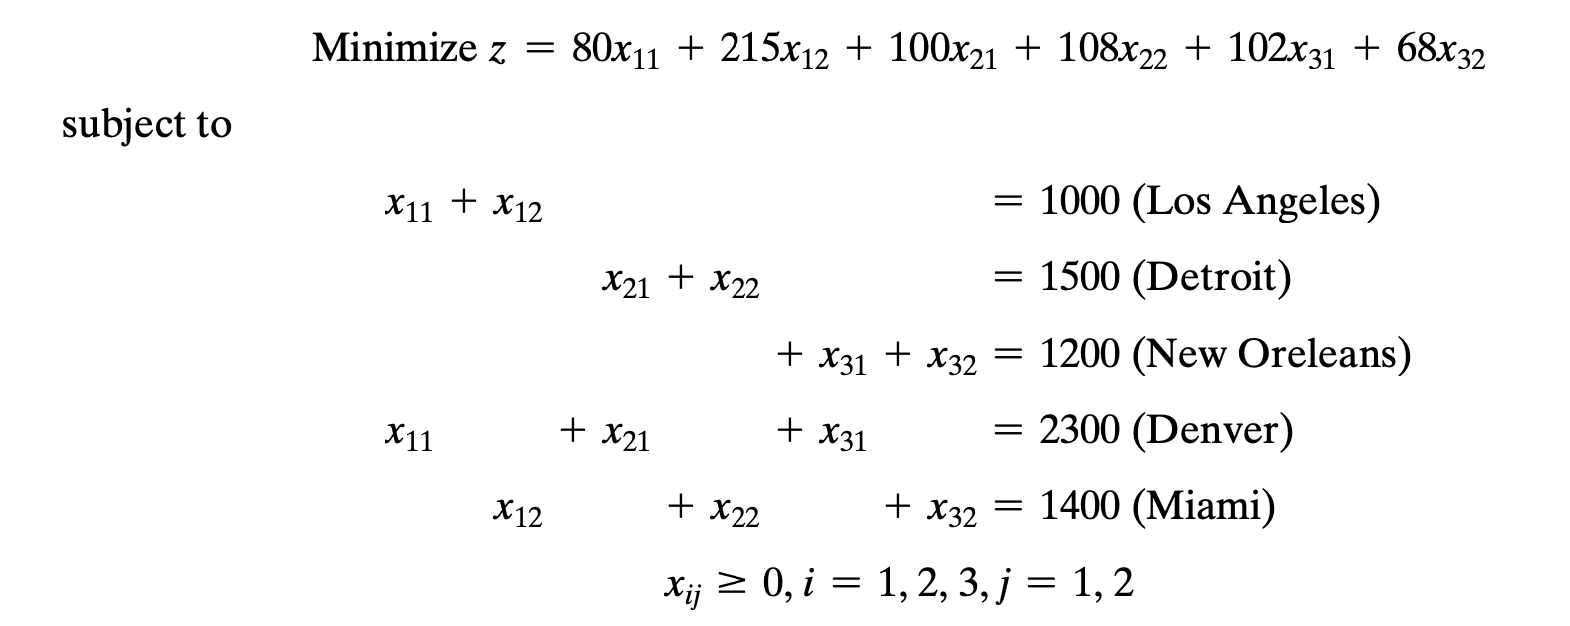

The special structure of the transportation problem allows a compact representation of the problem using the transportation tableau format in **Table 3**. This format is convenient for modeling many situations that do not deal with transporting goods.

**Table 3:** MG Transportation Model มาจากสมการข้างบน

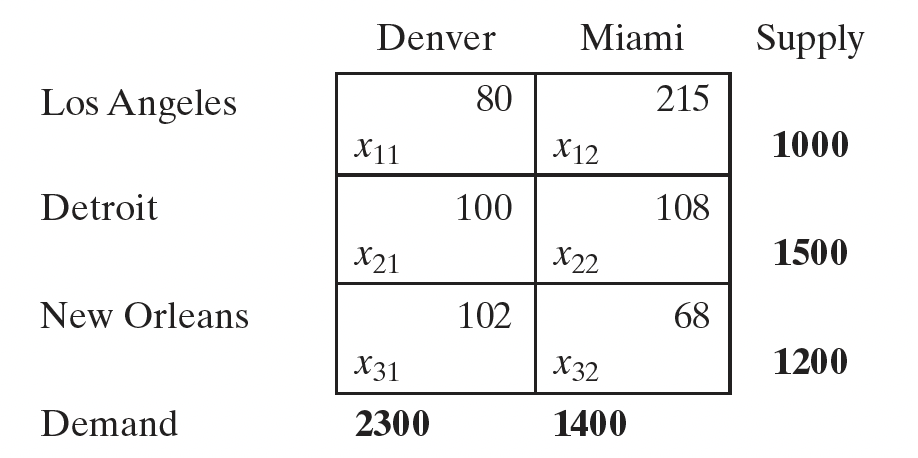

% Example 1

% f เป็น obj function
%ในแต่ละ path จะมีค่าขนส่งต่อคันเท่าไหร โดย f1 เป็น transpos vector
%การทำtranspos คือคั่นด้วย ; จะเป็น columb vector
% f1   = [80; 215; 100; 108; 102; 68];
% A1   = [1	1	0	0	0	0;
%         0	0	1	1	0	0;
%         0	0	0	0	1	1];
% Aeq1 = [1	0	1	0	1	0;
%         0	1	0	1	0	1];
% b1   = [1000; 1500; 1200];
% beq1 = [2300; 1400];
% lb1  = zeros(6,1);
% ub1  = [];

f1 =     80
   215
   100
   108
   102
    68


f1 = [80; 215; 100; 108; 102; 68]
A1 = [  1	1	0	0	0	0;
        0	0	1	1	0	0;
        0	0	0	0	1	1];
Aeq1 = [1	0	1	0	1	0;
        0	1	0	1	0	1;];
b1 = [1000; 1500; 1200];
beq1 = [2300; 1400];
lb1 = zeros(6,1);
ub1 = [];
[x1,fval1] = linprog(f1,A1,b1,Aeq1,beq1,lb1,ub1);


Optimal solution found.



disp(x1);

        1000
           0
        1300
         200
           0
        1200



%General form
% [x1, fval1, exitflag1, output1, lambda1] = linprog(f1, A1, b1, Aeq1, beq1, lb1, ub1);

% Display the results of the optimization
disp('Optimal solution (x1):');

Optimal solution (x1):


disp(x1);

        1000
           0
        1300
         200
           0
        1200



disp('Minimum transportation cost (fval1):');

Minimum transportation cost (fval1):


disp(fval1);

Unrecognized function or variable 'fval1'.

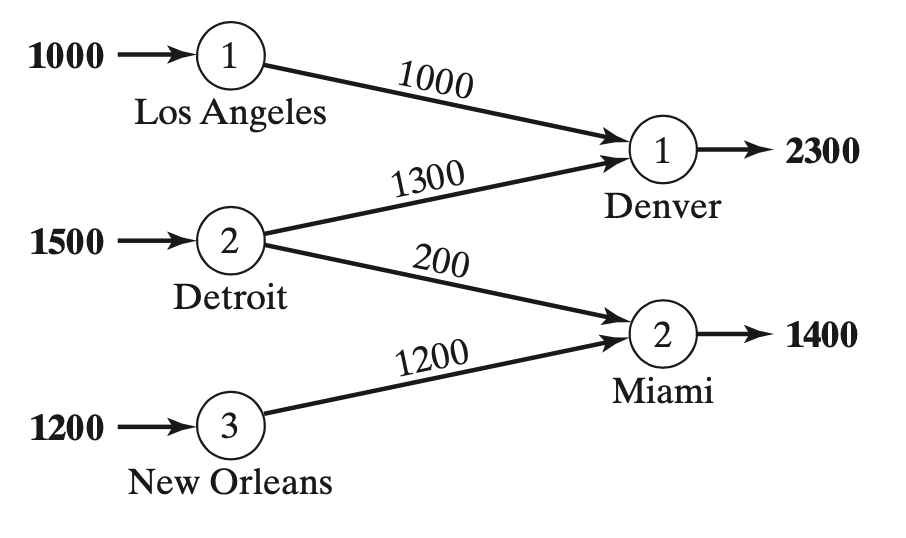

**Figure 2:** Optimal solution of MG Auto model 

The transportation problem in **Example 1** assumes that model is balanced, meaning that the total demand equals to the total supply (which happened to be true—coincidentally—in the MG model). If the model is unbalanced, a dummy source or a dummy destination must be added to restore balance. 			

## **Example 2: Over-demand** 

In the MG model, suppose that the Detroit plant capacity is 1300 cars (instead of 1500). The total supply (= 3500 cars) is less than the total demand (= 3700 cars), meaning that part of the demand at Denver and Miami will not be satisfied. Because the demand exceeds the supply, **a dummy plant** (source) with a capacity of 200 cars (= 3700 - 3500) is added to balance the model. The unit transportation cost from the dummy plant to the two destinations is **zero** because the plant does not exist.

**Table 4:** MG Model with Dummy Plant

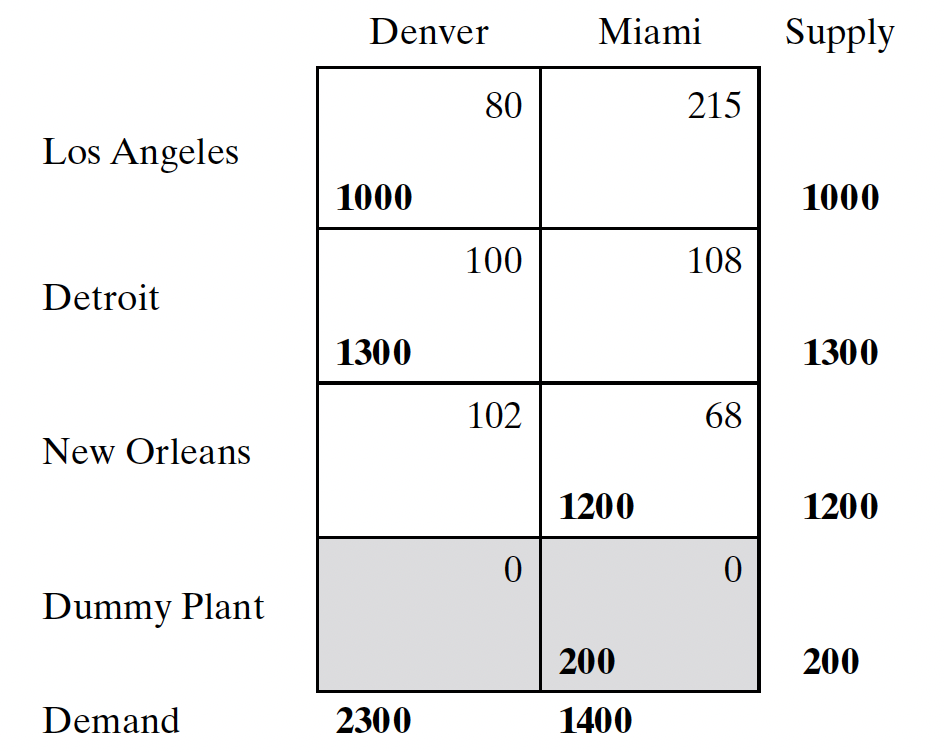

We can make sure that a specific destination does not experience shortage by assigning a **very high unit transportation cost** from the dummy source to that destination. For example, a **penalty** of $10,000 in the dummy-Miami cell will prevent shortage at Miami. Of course, we cannotuse this “trick” with all the destinations, because shortage must take place somewhere.

% Example 2

M = 10000; % Penalty
่
f2   = [80; 215; 100; 108; 102; 68;  0;  M];
A2   = [1	1	0	0	0	0	0	0;
        0	0	1	1	0	0	0	0;
        0	0	0	0	1	1	0	0;
        0	0	0	0	0	0	1	1];
Aeq2 = [1	0	1	0	1	0	1	0;
        0	1	0	1	0	1	0	1];
b2   = [1000; 1300; 1200; 200];
beq2 = [2300; 1400];
lb2  = zeros(8,1);
ub2  = [];

[x2, fval2, exitflag2, output2, lambda2] = linprog(f2, A2, b2, Aeq2, beq2, lb2, ub2);


Optimal solution found.




% Display the results of the optimization
disp('Optimal solution (x2):');

Optimal solution (x2):


disp(x2);

        1000
           0
        1100
         200
           0
        1200
         200
           0



disp('Minimum transportation cost (fval2):');

Minimum transportation cost (fval2):


disp(fval2);

      293200



## **Example 3: Over-supply** 

The case where the supply exceeds the demand can be demonstrated by assuming that the demand at Denver is 1900 cars only. In this case, we need to add a dummy distribution center to “receive” the surplus supply. Again, the unit transportation cost to the dummy distribution center is zero, unless we require a factory to “ship out” completely. In this case, a high unit transportation cost is assigned from the designated factory to the dummy destination. **Table 5** gives the new model and its optimal solution. The solution shows that the Detroit plant will have a surplus of 400 cars.

**Table 5:** MG Model with Dummy Destination

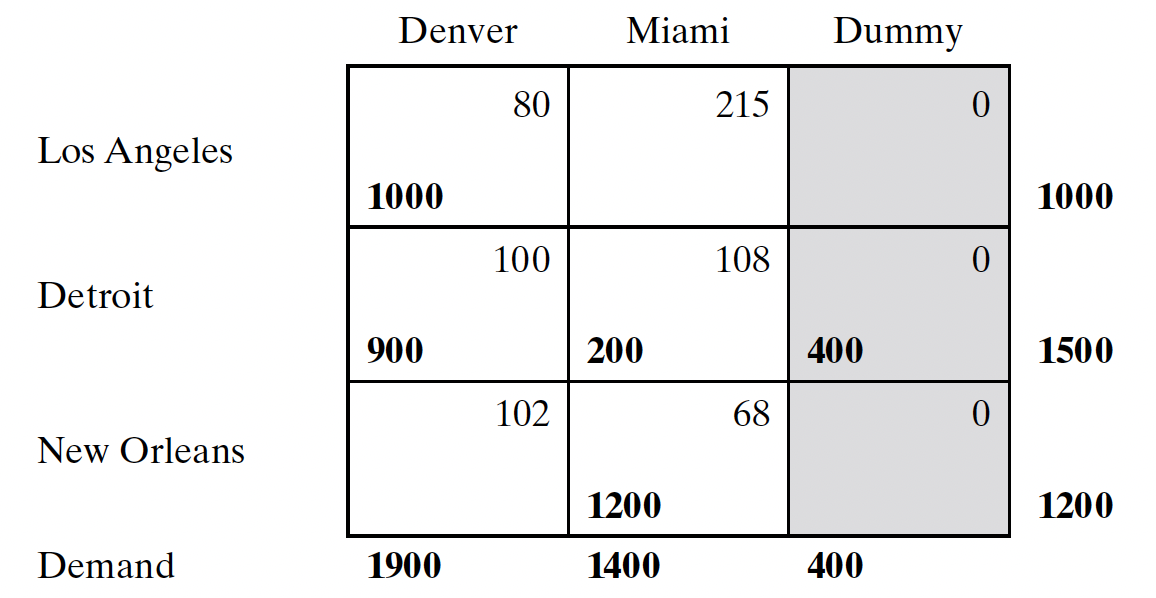

% Example 3

f3   = [80; 215; 0; 100; 108; 0; 102; 68;  0];
A3   = [1	1	1	0	0	0	0	0	0;
        0	0	0	1	1	1	0	0	0;
        0	0	0	0	0	0	1	1	1];
Aeq3 = [1	0	0	1	0	0	1	0	0;
        0	1	0	0	1	0	0	1	0;
        0	0	1	0	0	1	0	0	1];
b3   = [1000; 1500; 1200];
beq3 = [1900; 1400; 400];
lb3  = zeros(9,1);
ub3  = [];

[x3, fval3, exitflag3, output3, lambda3] = linprog(f3, A3, b3, Aeq3, beq3, lb3, ub3);


Optimal solution found.




% Display the results of the optimization
disp('Optimal solution (x3):');

Optimal solution (x3):


disp(x3);

        1000
           0
           0
         900
         200
         400
           0
        1200
           0



disp('Minimum transportation cost (fval3):');

Minimum transportation cost (fval3):


disp(fval3);

      273200



## **Example 4:** Production-Inventory Control

Boralis manufactures backpacks for serious hikers. The demand for its product during the peak period of March to June of each year is 100, 200, 180, and 300 units, respectively. The company uses part-time labor to accommodate fluctuations in demand. It is estimated that Boralis can produce 50, 180, 280, and 270 units in March through June. A current month’s demand may be satisfied in one of three ways.

- Current month’s production at the cost of $40 per pack.

- Surplus production in an earlier month at an additional holding cost of $.50 per pack per month

- Surplus production in a later month (back-ordering) at an additional penalty cost of $2.00 per pack per month.

Boralis wishes to determine the optimal production schedule for the four months.

The following table summarizes the parallels between the elements of the production-inventory problem and the transportation model:

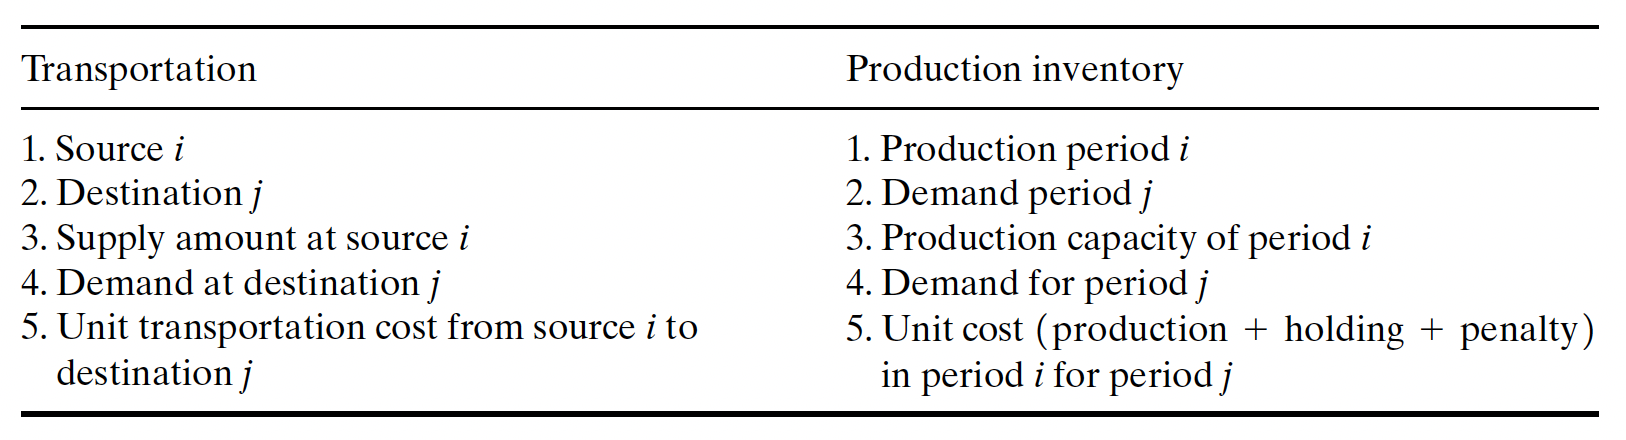

The resulting transportation model is given in **Table 6**.

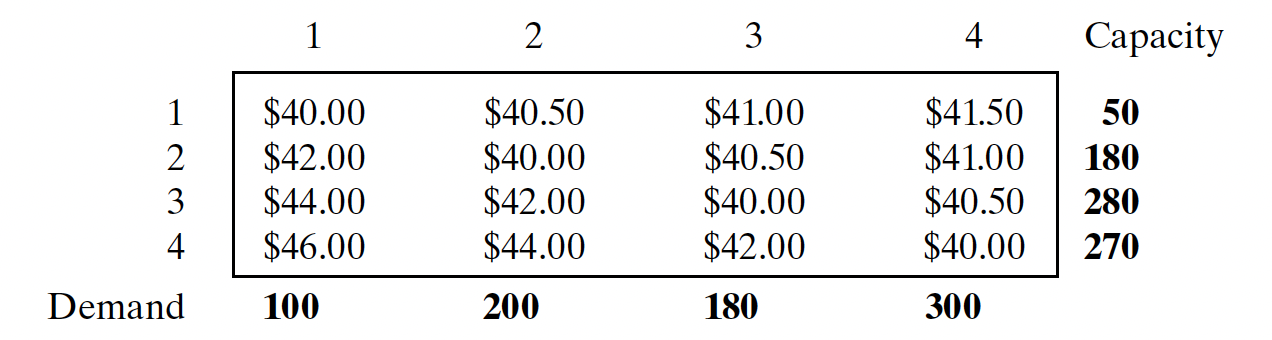

The unit “transportation” cost from period $i$ to period $j$ is computed as

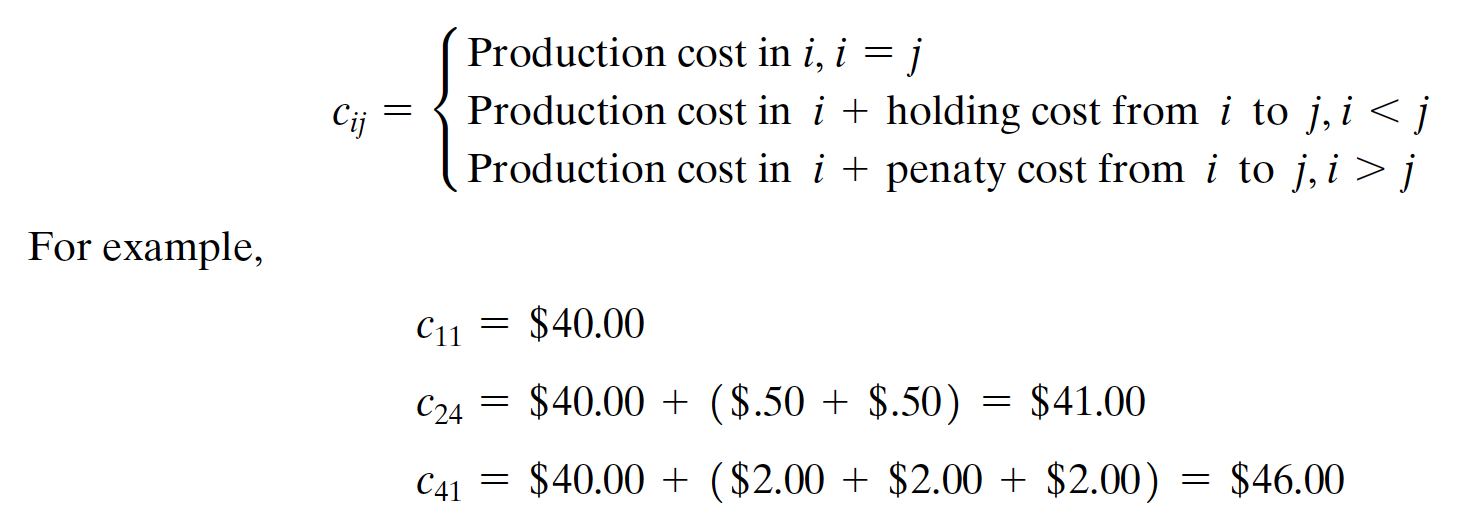

One of the optimal solution is summarized in **Figure 3**. The dashed lines indicate back-ordering, the dotted lines indicate production for a future period, and the solid lines show production in a period for itself. The total cost is $31,455.

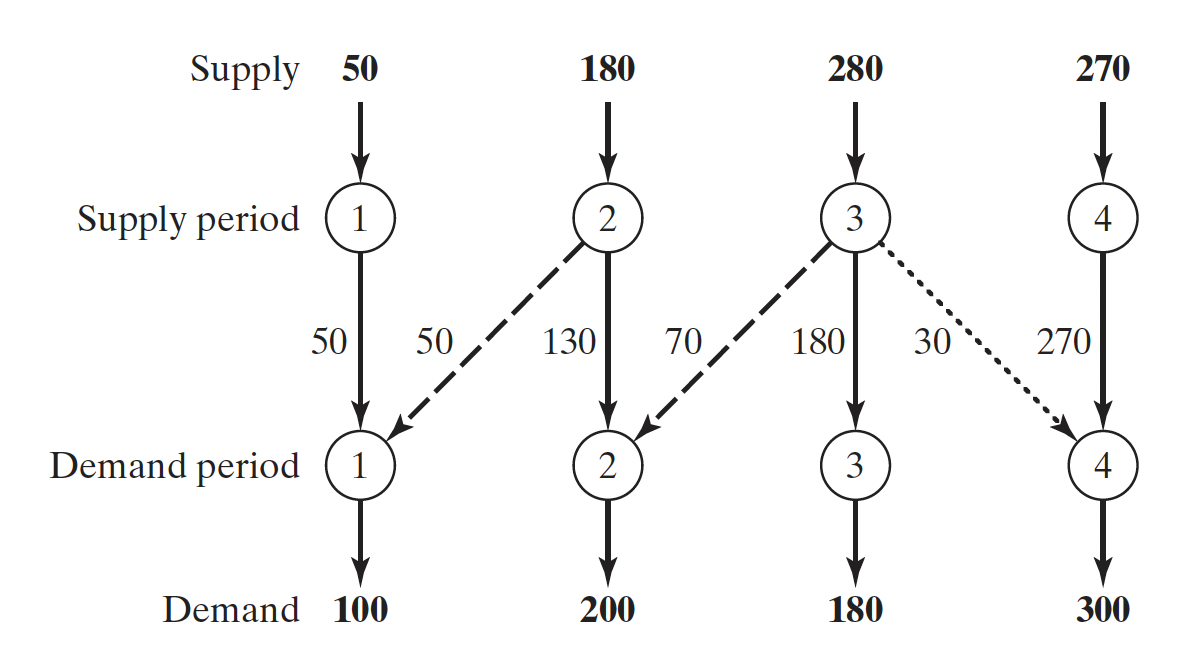

**Figure 3:** Optimal solution of the production-inventory model

% Example 4

f4   = [40;     40.5;   41;     41.5;
        42;     40;     40.5;   41;
        44;     42;     40;     40.5;
        46;     44;     42;     40];
A4   = [1	1	1	1	0	0	0	0	0	0	0	0	0	0	0	0;
        0	0	0	0	1	1	1	1	0	0	0	0	0	0	0	0;
        0	0	0	0	0	0	0	0	1	1	1	1	0	0	0	0;
        0	0	0	0	0	0	0	0	0	0	0	0	1	1	1	1];
Aeq4 = [1	0	0	0	1	0	0	0	1	0	0	0	1	0	0	0;
        0	1	0	0	0	1	0	0	0	1	0	0	0	1	0	0;
        0	0	1	0	0	0	1	0	0	0	1	0	0	0	1	0;
        0	0	0	1	0	0	0	1	0	0	0	1	0	0	0	1];
b4   = [50; 180; 280; 270];
beq4 = [100; 200; 180; 300];
lb4  = zeros(16,1);
ub4  = [];


Optimal solution found.




[x4, fval4, exitflag4, output4, lambda4] = linprog(f4, A4, b4, Aeq4, beq4, lb4, ub4);


Optimal solution (x4):


% Display the results of the optimization

    50
     0
     0
     0
    50
   130
     0
     0
     0
    70
   180
    30
     0
     0
     0
   270



disp('Optimal solution (x4):');

Minimum transportation cost (fval4):


disp(x4);

       31455



disp('Minimum transportation cost (fval4):');
disp(fval4);

## **Example 5:** Tool Sharpening

Arkansas Pacific operates a sawmill that produces boards from different types of lumber. Depending on the type of wood being milled, the demand for sharp blades varies from day to day according to the following 1-week (7-day) data:

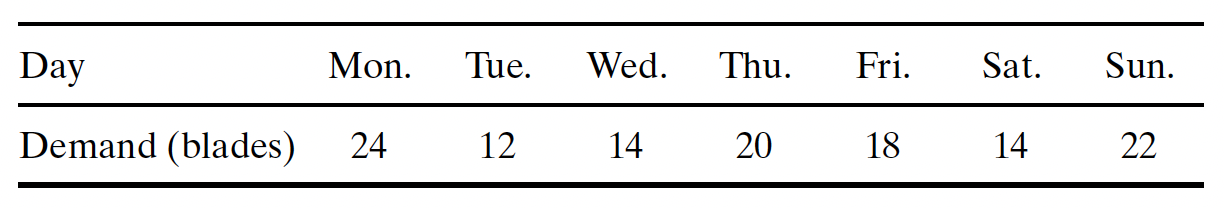

The mill can satisfy the daily demand in four ways:

- New blades at the cost of $12 a piece.

- Overnight sharpening service for $6 a blade.

- One-day sharpening service for $5 a blade.

- Two-day sharpening service for $3 a blade.

The situation can be represented as a transportation model with eight sources and seven destinations. The destinations represent the 7 days of the week. The sources of the model are defined as follows: Source 1 corresponds to buying new blades, which, in the extreme, can cover the demand for all 7 days 1= 24 + 12 + 14 + 20 + 18 + 14 + 22 = 1242. Sources 2 to 8 correspond to the 7 days of the week. The amount of supply for each of these sources equals the number of used blades at the end of the associated day. For example, source 2 (Monday) will have a supply of used blades equal to the demand for Monday. The unit “transportation cost” for the model is $12 for new blade, $6 for overnight sharpening, $5 for 1-day sharpening, or $3 all else. The “disposal” column is a dummy destination for balancing the model. The complete model and its solution are given in **Table 7**.

**Table 7: **Tool-Sharpening Problem Expressed as a Transportation Model

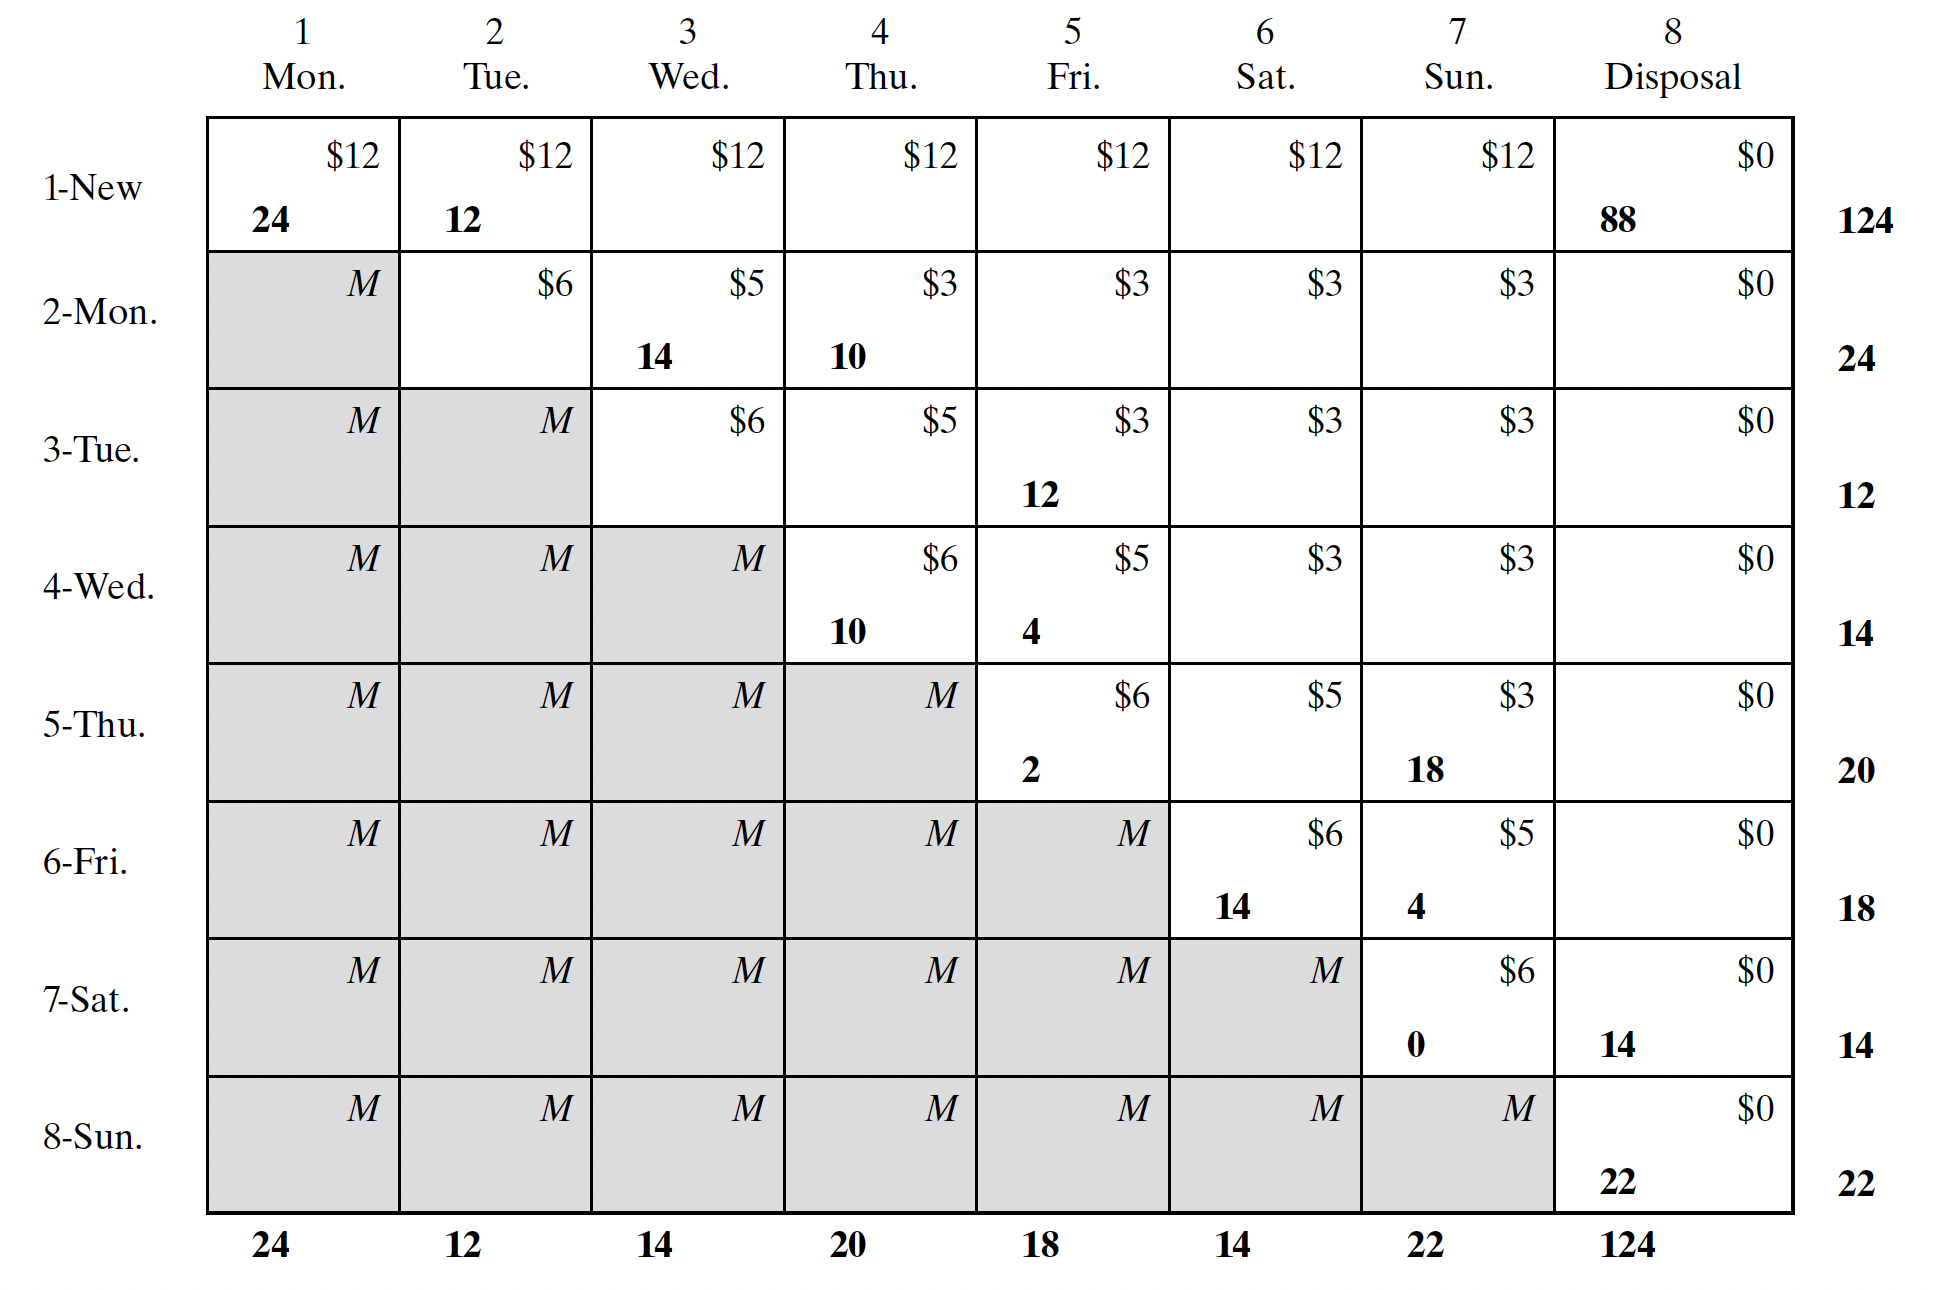

The following table summarizes one of the optimum solutions at a total cost of $818.

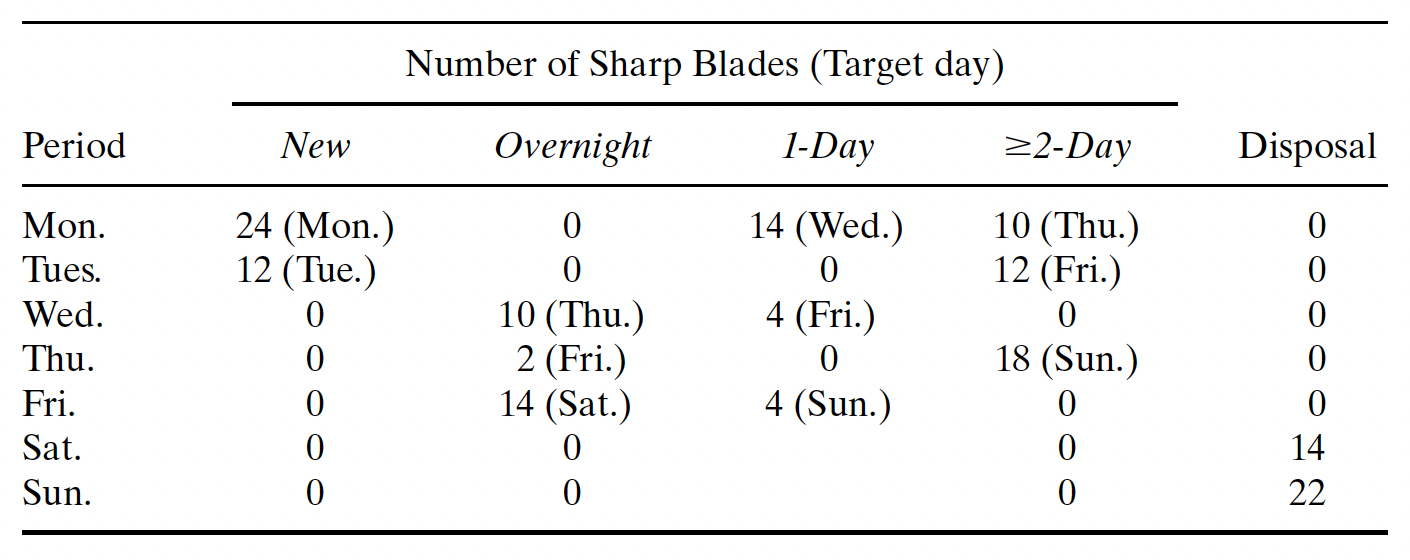

% Example 5

f5   = [12;	12;	12;	12;	12;	12;	12;	0;
        M;	6;	5;	3;	3;	3;	3;	0;
        M;	M;	6;	5;	3;	3;	3;	0;
        M;	M;	M;  6;  5;	3;	3;	0;
        M;	M;	M;	M;  6;	5;	3;	0;
        M;	M;	M;	M;	M;	6;	5;	0;
        M;	M;	M;	M;	M;	M;	6;	0;
        M;	M;	M;	M;	M;	M;	M;	0];
A5   = zeros(8,64);
for i = 1:8
    colrange = (i-1)*8+1:i*8;
    A5(i, colrange) = ones(1,8);
end
Aeq5 = [eye(8),eye(8),eye(8),eye(8),eye(8),eye(8),eye(8),eye(8)];


Optimal solution found.



b5   = [124; 24; 12; 14; 20; 18; 14; 22];
beq5 = [24;	12;	14;	20;	18;	14;	22;	124];
lb5  = zeros(64,1);
ub5  = [];
[x5, fval5, exitflag5, output5, lambda5] = linprog(f5, A5, b5, Aeq5, beq5, lb5, ub5);

x5_tbl = zeros(8,8);
for i = 1:8
    rowrange = (i-1)*8+1:i*8;

Optimal solution (x5):


    x5_tbl(i,:) = x5(rowrange)';

    24    12     0     0     0     0     0    88
     0     0    14    10     0     0     0     0
     0     0     0     0    12     0     0     0
     0     0     0    10     0     4     0     0
     0     0     0     0     6     0    14     0
     0     0     0     0     0    10     8     0
     0     0     0     0     0     0     0    14
     0     0     0     0     0     0     0    22



end

Minimum transportation cost (fval5):


   818



% Display the results of the optimization
disp('Optimal solution (x5):');
disp(x5_tbl);
disp('Minimum transportation cost (fval5):');
disp(fval5);

# Practice

## Question 1: Linear Programming

Medal company produces bronze medals from 5 types of raw material, A, B, C, D and E. The production needs to meet the following requirements.

- The percentage of copper must be at least 80 percent.

- The percentage of tin must be no more than 20 percent.

- The percentage of aluminum must be between 5 to 15 percent.

The characteristics of the raw material are shown in **Table 8**. Formulate this problem as a linear programming problem to find a production formula that achieves the lowest production cost and meets the desirable mixing proportion.

**Table 8:** The Characteristics of Raw Material for the Medal Production

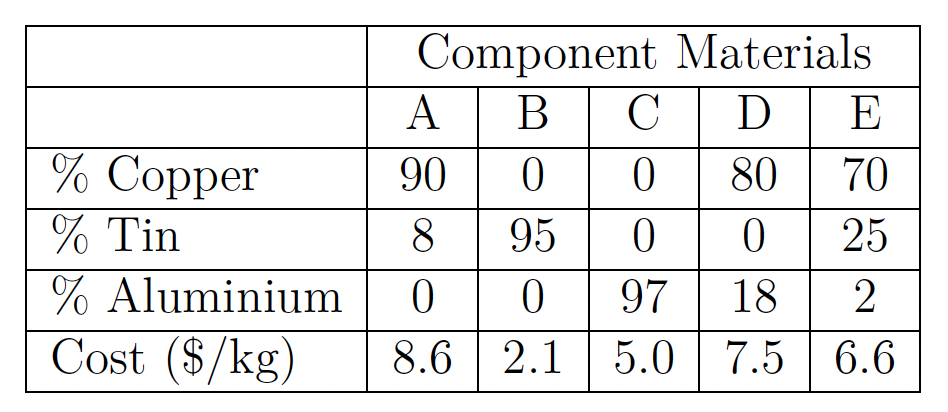

% Question 1



## Question 2: Transshipment Problem

General Ford has two plants, two warehouses, and three customers. The locations of these are as follows:

- Plants: Detroit and Atlanta

- Warehouses: Denver and New York

- Customers: Los Angeles, Chicago, and Philadelphia

Cars are produced at plants, then shipped to warehouses, and finally shipped to customers. Detroit can produce 150 cars per week, and Atlanta can produce 100 cars per week. Los Angeles requires 100 cars per week; Chicago, 70; and Philadelphia, 80. It costs $10,000 to produce a car at each plant, and the cost of shipping a car between two cities is given in **Table 9**. Determine how to meet General Ford’s weekly demands at minimum cost.

**Table 9:** The Cost of Shipping a Car

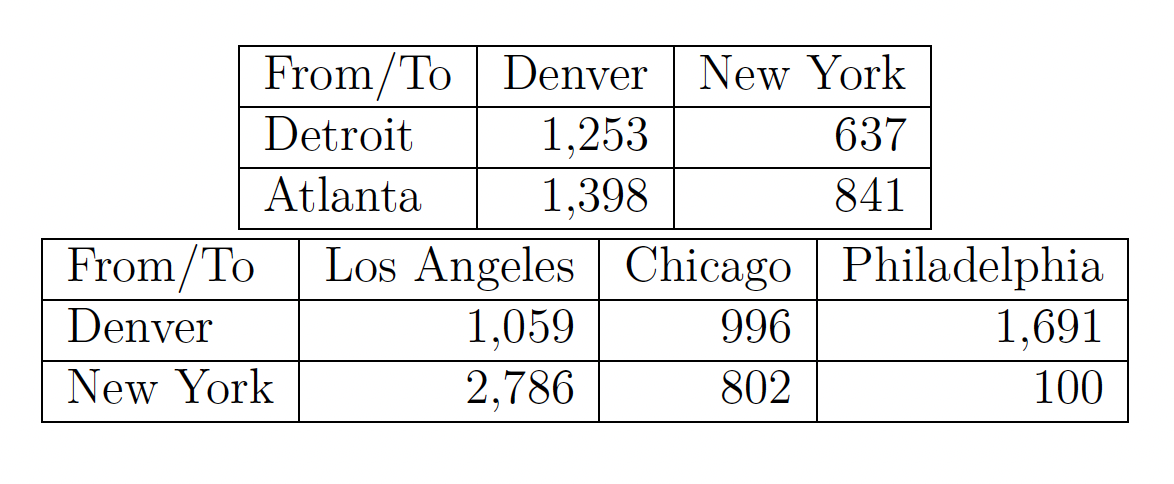

% Question 2



## Question 3: Transportation Problem

Periodic preventive maintenance is carried out on aircraft engines, where an important component must be replaced. The numbers of aircraft scheduled for such maintenance over the next six months are estimated at 200, 180, 300, 198, 230, and 290, respectively. All maintenance work is done during the first day of the month, where a used component may be replaced with a new or an overhauled component. The overhauling of used components may be done in a local repair facility, where they will be ready for use at the beginning of next month, or they may be sent to a central repair shop, where a delay of 3 months (including the month in which maintenance occurs) is expected. The repair cost in the local shop is $120 per component. At the central facility, the cost is only $35 per component. An overhauled component used in a later month will incur an additional storage cost of $1.50 per unit per month. New components may be purchased at $200 each in month 1, with a 5% price increase every 2 months. Formulate the problem as a transportation model, and determine the optimal schedule for satisfying the demand for the component over the next six months.

% Question 3



`End-of-file`

`Pongsun B.`

`2025-10-09`